%% MEG data

adults = 1

adults = 0

if adults~=1
    %Children
    meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Child_MEG\2872'
    meg_file = '2872_CM_ME125_2018_01_12_B1_denoise_rethm.con'  % your exported con-filename

    

    % %Children
    audio_ch        = 135; % Audio event from fOMRI
    every_trigger   = 145  % spikes every event (every 500ms)
    trig_chans      = 146:152 % 7-tone
    other_ch        = 192  % Unsure what this is, roughly is on/off while any event is occurring

end

meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Child_MEG\2872'

meg_file = '2872_CM_ME125_2018_01_12_B1_denoise_rethm.con'

every_trigger = 145

trig_chans =    146   147   148   149   150   151   152


other_ch = 192



if adults == 1
    % Adults
    meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Adult_MEG\2737\'
    % meg_file = '2737_KY_ME125_2017_10_20_B1.con';  % Resting state
    % meg_file = '2737_KY_ME125_2017_10_20_B2.con';  % Resting state
    meg_file = '2737_KY_ME125_2017_10_20_B3.con'  % Roving oddball
    % meg_file = '2737_KY_ME125_2017_10_20_B4.con';  % Resting state

    %%Probable event channels
    %Adults
    audio_ch = 166;        % Audio event from fOMRI  
    every_trigger = 193;   % spikes every event (every 500ms)
    trig_chans = 194:204   % 11 tones
    trig_chans = 194:200   % 7-tone
    other_ch   = 256  % Unsure what this is, roughly is on/off while any event is occurring
    
end


% chan_analog = 192; % Unknown information in this channel (result usually 0, occasionally 5) 
% % See meetings
% %trig_chans = 129:134 # Noise category A
% %trig_chans = 136:144 # noise category A
% %trig_chans = 145:152 # noise category B
% %trig_chans = 153:159 # noise category A
% %trig_chans = [184 185 186];

dataset = fullfile(meg_path, meg_file);

event = ft_read_event(dataset, 'dataformat','yokogawa_con', 'threshold', 1.6, 'chanindx', trig_chans, 'detectflank', 'up')% , ); % , 

event = 1×1775 struct array with fields:
    type
    sample
    value
    offset
    duration


hdr = ft_read_header(dataset, 'dataformat','yokogawa_con');

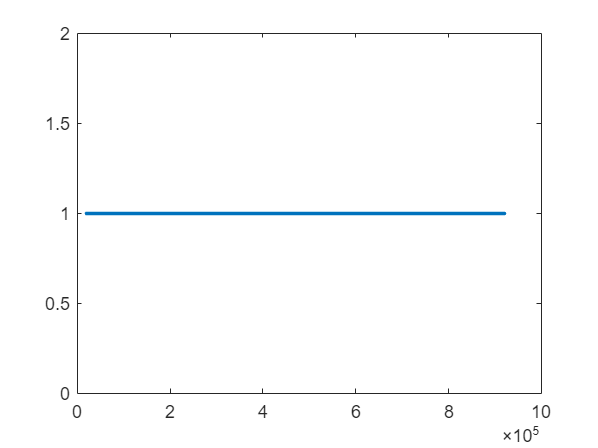

% search for "trigger" events
plot([event.sample], [event.value], '.')

disp(unique({event.type}))

    {'146'}    {'147'}    {'148'}    {'149'}    {'150'}    {'151'}    {'152'}



value  = [event(find(strcmp('trigger', {event.type}))).value]'


value =

     []



sample = [event(find(strcmp('trigger', {event.type}))).sample]';
disp(value)
disp(sample)

% Read output from fieldtrip
data = ft_read_data(dataset)

data =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000  

% % Read output from MNE
% data = ft_read_data('F:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Child_MEG\2872\2872_CM_ME125_2018_01_12_B1_denoise_rethm_raw_tsss.fif')

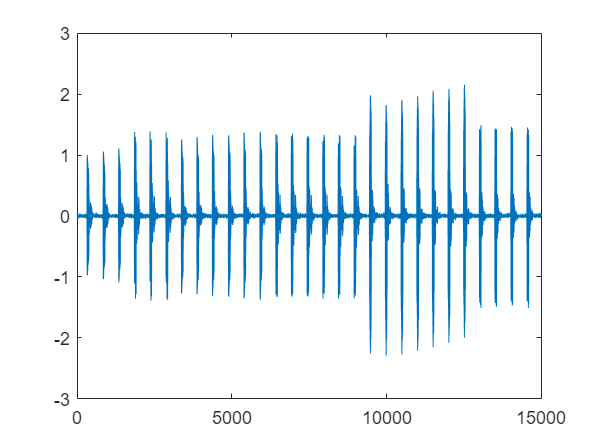

% Examine audio bit
duration = 15;
start_secs = 25;
end_secs = start_secs + duration;
dat = ft_read_data(dataset, 'begsample', start_secs*1000, 'endsample', end_secs*1000, 'chanindx', audio_ch);
plot(dat)

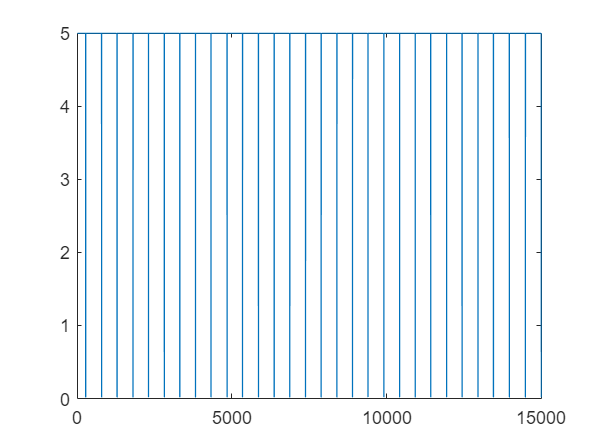

% Examine every trigger bit
dat = ft_read_data(dataset, 'begsample', start_secs*1000, 'endsample', end_secs*1000, 'chanindx', every_trigger);
plot(dat)

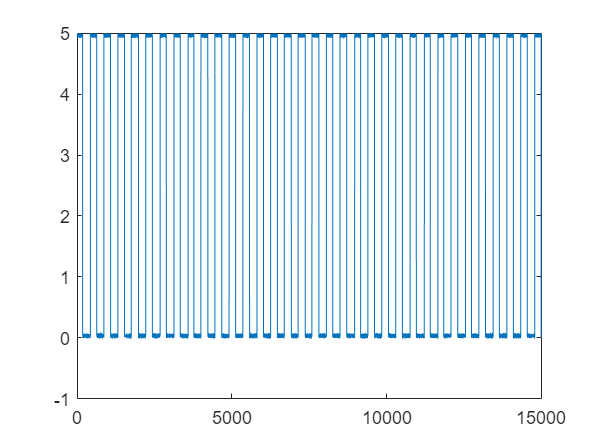

% Examine a piece of data
dat = ft_read_data(dataset, 'begsample', start_secs*1000, 'endsample', end_secs*1000, 'chanindx', other_ch);
plot(dat)

start_plotting = 25*1000 % 25 secs in is when data normally begins

start_plotting = 25000

146 , 50


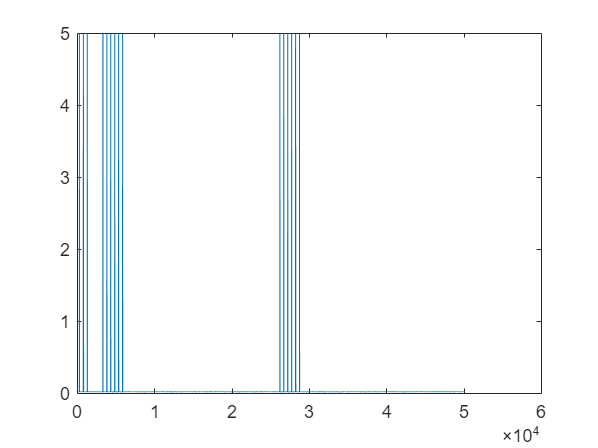

147 , 50


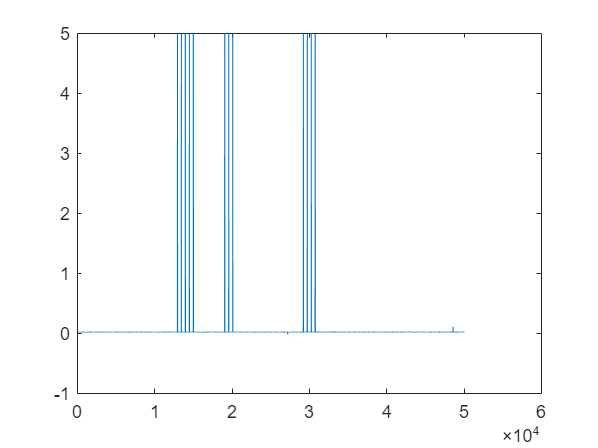

148 , 50


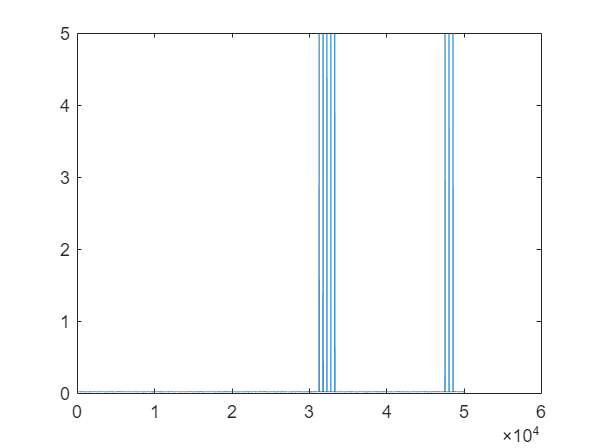

149 , 50


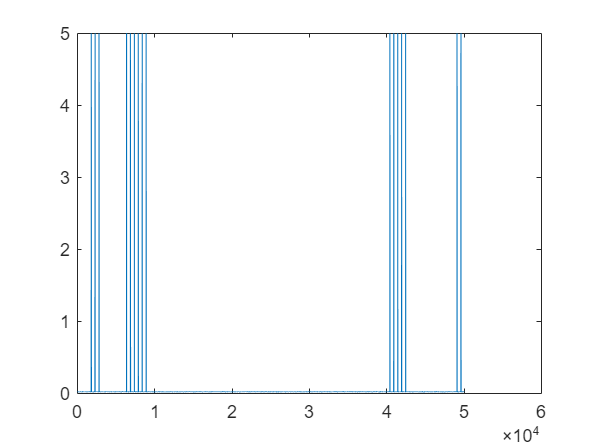

150 , 50


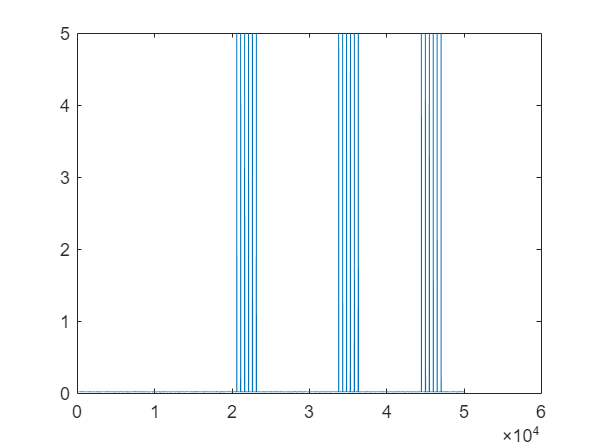

151 , 50


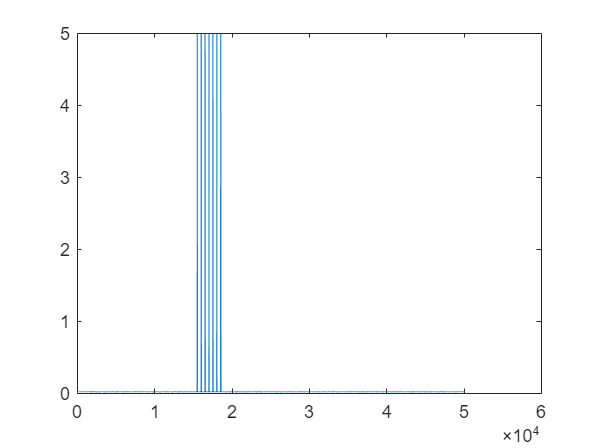

152 , 50


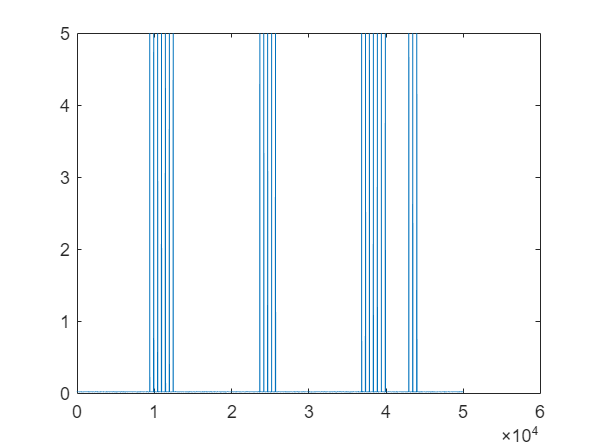

for chan_num = trig_chans % [audio_ch,chan_analog] 
    for plot_length = [50] % [30 10] % Various lengths in secs
        disp(strcat(num2str(chan_num), " , ", num2str(plot_length)))
            % At the lowest zoom level, 
        figure;
        plot(data(chan_num,start_plotting:(start_plotting+plot_length*1000)));
    end
end

% -> % Unsure what chan_analog is, using every_trigger
% the low and high signal are most easily visible
% Halfway between high and low is a good threshold for detecting the event

## More basic code

% From ME125 - Phase 2 - Step 1

cfg                         = [];
cfg.dataset                 = dataset;
cfg.headerfile              = dataset;
cfg.datafile                = dataset;
cfg.trialfun                = 'ft_trialfun_general';  

cfg.channel                 = hdr.grad.label; 
%cfg.channel                = 'AG*';
%cfg.channel                = '161'; % 19*'; %chan_analog
%cfg.channel                = 'all'
%cfg.channel                = 'TRIG*'

cfg.continuous              = 'yes';

%highpass filter
cfg.hpfilter                = 'yes';
cfg.hpfiltwintype           = 'blackman';
cfg.hpfilttype              = 'firws';          %'but'  'firws'
cfg.hpfiltdir               = 'onepass-zerophase';
cfg.hpfreq                  = 0.1;              %FIXME should try something lower to appease reviewers 0.1
cfg.hpfiltdf                = 0.15;             % highpass transition width
%cfg.hpfiltord               = 6;                % highpass filter order
cfg.dftfreq                 = 50;               % removal line noise

data                        = ft_preprocessing(cfg);

processing channel { 'AG001' 'AG002' 'AG003' 'AG004' 'AG005' 'AG006' 'AG007' 'AG008' 'AG009' 'AG010' 'AG011' 'AG012' 'AG013' 'AG014' 'AG015' 'AG016' 'AG017' 'AG018' 'AG019' 'AG020' 'AG021' 'AG022' 'AG023' 'AG024' 'AG025' 'AG026' 'AG027' 'AG028' 'AG029' 'AG030' 'AG031' 'AG032' 'AG033' 'AG034' 'AG035' 'AG036' 'AG037' 'AG038' 'AG039' 'AG040' 'AG041' 'AG042' 'AG043' 'AG044' 'AG045' 'AG046' 'AG047' 'AG048' 'AG049' 'AG050' 'AG051' 'AG052' 'AG053' 'AG054' 'AG055' 'AG056' 'AG057' 'AG058' 'AG059' 'AG060' 'AG061' 'AG062' 'AG063' 'AG064' 'AG065' 'AG066' 'AG067' 'AG068' 'AG069' 'AG070' 'AG071' 'AG072' 'AG073' 'AG074' 'AG075' 'AG076' 'AG077' 'AG078' 'AG079' 'AG080' 'AG081' 'AG082' 'AG083' 'AG084' 'AG085' 'AG086' 'AG087' 'AG088' 'AG089' 'AG090' 'AG091' 'AG092' 'AG093' 'AG094' 'AG095' 'AG096' 'AG097' 'AG098' 'AG099' 'AG100' 'AG101' 'AG102' 'AG103' 'AG104' 'AG105' 'AG106' 'AG107' 'AG108' 'AG109' 'AG110' 'AG111' 'AG112' 'AG113' 'AG114' 'AG115' 'AG116' 'AG117' 'AG118' 'AG119' 'AG120' 'AG121' 'AG122' 'AG


%lowpass filter
cfg                         = [];
cfg.lpfilter                = 'yes';
cfg.lpfilttype              = 'firws';              %'but'  'firws'
cfg.lpfiltwintype           = 'blackman';           % lowpass window type, 'hann' or 'hamming' (default) or 'blackman' or 'kaiser' (firws)
cfg.lpfiltdir               = 'onepass-zerophase';  % filter direction, 'twopass' (default), 'onepass' or 'onepass-reverse' or 'onepass-zerophase' (default for firws) or 'onepass-minphase' (firws, non-linear!)
cfg.lpfreq                  = 30;
cfg.lpfiltdf                = 10;

%band stop filter
cfg.bsfilter                = 'yes';
cfg.bsfreq                  = [49.5 50.5];

data                        = ft_preprocessing(cfg,data); 

the call to "ft_selectdata" took 0 seconds
preprocessing
Lowpass filtering data: onepass-zerophase, order 550, blackman-windowed sinc FIR
  cutoff (-6 dB) 30 Hz
  transition width 10.0 Hz, passband 0-25.0 Hz, stopband 35.0-500 Hz
  maximum passband deviation 0.0002 (0.02%), stopband attenuation -74 dB
preprocessing trial 1 from 1



% Convert a fieldtrip object to an MNE object
fiff_file  = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Child_MEG\2872\FieldTrip data MAT to MNE data FIF.fif'

fiff_file = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Child_MEG\2872\FieldTrip data MAT to MNE data FIF.fif'

fieldtrip2fiff(fiff_file, data)


Copyright (c) 2011, Matti Hamalainen and Alexandre Gramfort
All rights reserved.

Redistribution and use in source and binary forms, with or without
modification, are permitted provided that the following conditions are met:
    * Redistributions of source code must retain the above copyright
      notice, this list of conditions and the following disclaimer.
    * Redistributions in binary form must reproduce the above copyright
      notice, this list of conditions and the following disclaimer in the
      documentation and/or other materials provided with the distribution.
    * Neither the name of the Massachusetts General Hospital nor the
      names of its contributors may be used to endorse or promote products
      derived from this software without specific prior written permission.

THIS SOFTWARE IS PROVIDED BY THE COPYRIGHT HOLDERS AND CONTRIBUTORS "AS IS" AND
ANY EXPRESS OR IMPLIED WARRANTIES, I

%% Display waveforms using ft_databrowser
cfg = [];
cfg.blocksize = 10;
cfg = ft_databrowser(cfg, data);

the input is raw data with 125 channels and 1 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:
Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.

the call to "ft_databrowser" took 582 seconds


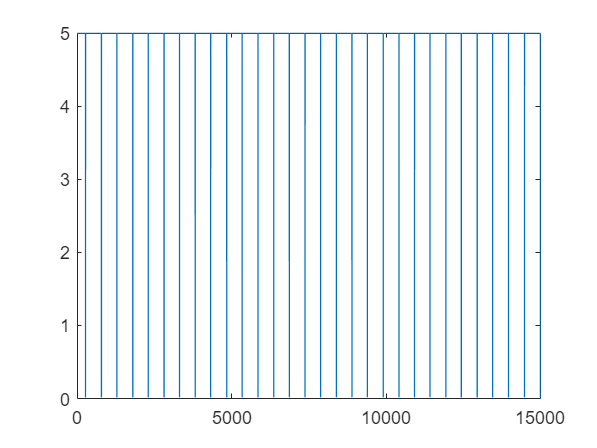

% Examine a piece of data
dat = ft_read_data(dataset, 'begsample', start_secs*1000, 'endsample', end_secs*1000, 'chanindx', every_trigger);
plot(dat)

% Scan other channels, plot those channels with things detected
events = struct('channel', num2cell(chans))

events = 1×67 struct array with fields:
    channel


cutoff_num_events = 100

cutoff_num_events = 100

   146



event = 1×224 struct array with fields:
    type
    sample
    value
    offset
    duration


Channel: 146 events: 224


   147



event = 1×224 struct array with fields:
    type
    sample
    value
    offset
    duration


Channel: 147 events: 224


   148



event = 1×277 struct array with fields:
    type
    sample
    value
    offset
    duration


Channel: 148 events: 277


   149



event = 1×251 struct array with fields:
    type
    sample
    value
    offset
    duration


Channel: 149 events: 251


   150



event = 1×295 struct array with fields:
    type
    sample
    value
    offset
    duration


Channel: 150 events: 295


   151



event = 1×231 struct array with fields:
    type
    sample
    value
    offset
    duration


Channel: 151 events: 231


   152



event = 1×273 struct array with fields:
    type
    sample
    value
    offset
    duration


Channel: 152 events: 273


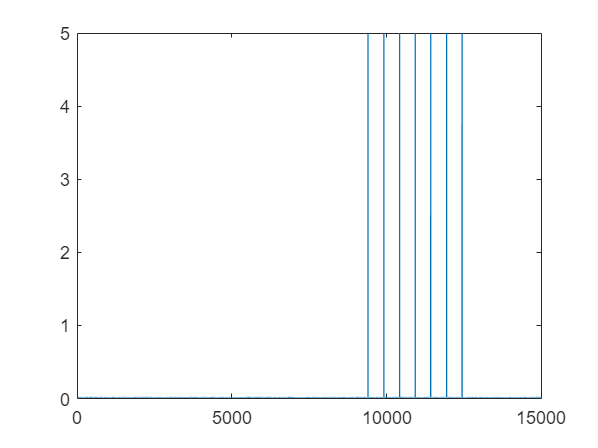

for chan = trig_chans
    disp(chan)
    event = ft_read_event(dataset, 'dataformat','yokogawa_con', 'threshold', 1.6, 'chanindx', chan, 'detectflank', 'up')% , ); % , 
    events(chan).channel = event;
    length_structure = structfun(@(field) length(field),events(chan));
    if length_structure > cutoff_num_events;
        disp(strcat("Channel: ", num2str(chan), " events: ", num2str(length_structure)))
        dat = ft_read_data(dataset, 'begsample', start_secs*1000, 'endsample', end_secs*1000, 'chanindx', chan);        plot(dat)
        plot(dat)
    end
end

% Scan known channel
event = ft_read_event(dataset,   'dataformat','yokogawa_con',  'threshold', 1.6, 'chanindx', trig_chans(1), 'detectflank', 'up')% , ); % , 

event = 1×224 struct array with fields:
    type
    sample
    value
    offset
    duration


% event = ft_read_event(dataset, 'dataformat','yokogawa_con',  'threshold', 1.6, 'chanindx', trig_chans,  'detectflank', 'up' ) % No triggers detected, we are below threshold

table = struct2table(event);
table(1:14,:)

ans = 14×5 table
     type      sample    value       offset         duration  
    _______    ______    _____    ____________    ____________

    {'146'}    23751       1      {0×0 double}    {0×0 double}
    {'146'}    24251       1      {0×0 double}    {0×0 double}
    {'146'}    24764       1      {0×0 double}    {0×0 double}
    {'146'}    25264       1      {0×0 double}    {0×0 double}
    {'146'}    25779       1      {0×0 double}    {0×0 double}
    {'146'}    26279       1      {0×0 double}    {0×0 double}
    {'146'}    28307       1      {0×0 double}    {0×0 double}
    {'146'}    28816       1      {0×0 double}    {0×0 double}
    {'146'}    29316       1      {0×0 double}    {0×0 double}
    {'146'}    29835       1      {0×0 double}    {0×0 double}
    {'146'}    30336       1      {0×0 double}    {0×0 d

%Examine a dat piece - more complex, for if triggers are defined properly
dataset = fullfile(meg_path, meg_file);
hdr   = ft_read_header(dataset);

cfg =[];
cfg.dataset                 = dataset;
cfg.headerfile              = dataset;
cfg.datafile                = dataset;
cfg.trialfun                = 'ft_trialfun_general'; 


cfg.channel                 = hdr.grad.label; 
%cfg.channel                = 'AG*';
%cfg.channel                = '161'; % 19*'; %chan_analog
%cfg.channel                = 'all'
%cfg.channel                = 'TRIG*'

%highpass filter
cfg.hpfilter                = 'yes';
cfg.hpfiltwintype           = 'blackman';
cfg.hpfilttype              = 'firws';          %'but'  'firws'
cfg.hpfiltdir               = 'onepass-zerophase';
cfg.hpfreq                  = 0.1;              %FIXME should try something lower to appease reviewers 0.1
cfg.hpfiltdf                = 0.15;             % highpass transition width
%cfg.hpfiltord               = 6;                % highpass filter order
cfg.dftfreq                 = 50;               % removal line noise

data                        = ft_preprocessing(cfg,data);

 In ft_checkconfig at line 226
 In ft_preprocessing at line 291

the call to "ft_selectdata" took 0 seconds
preprocessing
Highpass filtering data: onepass-zerophase, order 36668, blackman-windowed sinc FIR
  cutoff (-6 dB) 0.1 Hz
  transition width 0.1 Hz, stopband 0-0.0 Hz, passband 0.2-500 Hz
  maximum passband deviation 0.0002 (0.02%), stopband attenuation -74 dB
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 331 seconds



%lowpass filter
cfg                         = [];
cfg.lpfilter                = 'yes';
cfg.lpfilttype              = 'firws';              %'but'  'firws'
cfg.lpfiltwintype           = 'blackman';           % lowpass window type, 'hann' or 'hamming' (default) or 'blackman' or 'kaiser' (firws)
cfg.lpfiltdir               = 'onepass-zerophase';  % filter direction, 'twopass' (default), 'onepass' or 'onepass-reverse' or 'onepass-zerophase' (default for firws) or 'onepass-minphase' (firws, non-linear!)
cfg.lpfreq                  = 30;
cfg.lpfiltdf                = 10;

%band stop filter
cfg.headerfile              = dataset;
cfg.trialfun                = 'ft_trialfun_general'; 
cfg.bsfilter                = 'yes';
cfg.bsfreq                  = [49.5 50.5];
data                        = ft_preprocessing(cfg,data);

 In ft_checkconfig at line 226
 In ft_preprocessing at line 291

the call to "ft_selectdata" took 0 seconds
preprocessing
Lowpass filtering data: onepass-zerophase, order 550, blackman-windowed sinc FIR
  cutoff (-6 dB) 30 Hz
  transition width 10.0 Hz, passband 0-25.0 Hz, stopband 35.0-500 Hz
  maximum passband deviation 0.0002 (0.02%), stopband attenuation -74 dB
preprocessing trial 1 from 1






event = ft_read_event(dataset, 'threshold', 1.6, 'chanindx', trig_chans, 'detectflank', 'up'); % 166 % 'trigindx', audio_ch
event = ft_read_event(dataset, 'threshold', 1.6, 'chanindx', every_trigger, 'detectflank', 'up'); % 166 % 'trigindx', audio_ch


trl = [];

cfg.trialdef.eventtype = event.type;
% cfg.trialdef.eventtype  = 'analogtrig'; % use 'trial' for Yokogawa data
cfg.trialdef.eventvalue = event.value;
% cfg.trialdef.eventvalue = 1;
cfg.trialdef.prestim = 0.1;
cfg.trialdef.poststim = 0.4;
cfg.trigindx = every_trigger % 'chanindx' % chan_event chan_event ^ 192

cfg = struct with fields:
         lpfilter: 'yes'
       lpfilttype: 'firws'
    lpfiltwintype: 'blackman'
        lpfiltdir: 'onepass-zerophase'
           lpfreq: 30
         lpfiltdf: 10
       headerfile: 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Child_MEG\2872\2872_CM_ME125_2018_01_12_B1_denoise_rethm.con'
         trialfun: 'ft_trialfun_general'
         bsfilter: 'yes'
           bsfreq: [49.5000 50.5000]
         trialdef: [1×1 struct]
         trigindx: 145


cfg = ft_definetrial(cfg);

evaluating trialfunction 'ft_trialfun_general'
reading the header from 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Child_MEG\2872\2872_CM_ME125_2018_01_12_B1_denoise_rethm.con'
reading the events from 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Child_MEG\2872\2872_CM_ME125_2018_01_12_B1_denoise_rethm.con'


 In read_yokogawa_event at line 147
 In ft_read_event at line 2244
 In ft_trialfun_general at line 105
 In ft_definetrial at line 183

found 0 events


Error using ft_definetrial (line 201)
no trials were defined, see FT_DEFINETRIAL for help


for i=1:length(event)
if strcmp(event(i).type, cfg.trialdef.eventtype)
  % it is a trigger, see whether it has the right value
  if ismember(event(i).value, cfg.trialdef.eventvalue)
    % add this to the trl definition
    begsample     = event(i).sample - cfg.trialdef.prestim*hdr.Fs;
    endsample     = event(i).sample + cfg.trialdef.poststim*hdr.Fs - 1;
    offset        = -cfg.trialdef.prestim*hdr.Fs;
    trigger       = event(i).value; % remember the trigger (=condition) for each trial
    if isempty(trl)
      prevtrigger = nan;
    else
      prevtrigger   = trl(end, 4); % the condition of the previous trial
    end
    trl(end+1, :) = [round([begsample endsample offset])  trigger prevtrigger];
  end
end
end

% %Filter
% 
% %Delete non-beeps
% for i = length(data.trialinfo):-1:1
%   data.trialinfo(i).latency = data.trialinfo(i).latency+12; 
%  
%    if strcmp(strtok(data.trialinfo(i).type, 'N'), 'DI') ~= 1
%       data.trialinfo(i) = []; 
%    else
%         [~, trigger]  = strtok(data.trialinfo(i).type, 'N'); % remember the trigger (=condition) for each trial
%         trigger = str2double(trigger(2));
%         data.trialinfo(i).tone = trigger;
%    end
% end

function [trl, event] = mytrialfun(cfg)

% read the header information (including the sampling rate) and the events from the data
hdr   = ft_read_header(cfg.dataset);
event = ft_read_event(cfg.dataset, 'threshold', 1.6, 'chanindx', trig_chans, 'detectflank', 'up');

% search for "trigger" events according to 'trigchannel' defined outside the function
value  = [event(find(strcmp(cfg.trialdef.trigchannel, {event.type}))).value]';
sample = [event(find(strcmp(cfg.trialdef.trigchannel, {event.type}))).sample]';

% creating your own trialdefinition based upon the events
trl = [];
for j = 1:length(value);
  trlbegin = sample(j) - round(cfg.trialdef.prestim  * hdr.Fs);
  trlend   = sample(j) + round(cfg.trialdef.poststim * hdr.Fs);
  offset   = -round(cfg.trialdef.prestim  * hdr.Fs);
  newtrl   = [ trlbegin trlend offset];
  trl      = [ trl ; newtrl];
end
end